# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.5 多个折线图并列显示且具备各自独立坐标系

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/527384378/answer/2436508897](https://www.zhihu.com/question/527384378/answer/2436508897)

# 想要多个折线图并列显示且具备各自独立坐标系，大佬们有啥方案嘛？

类似这样

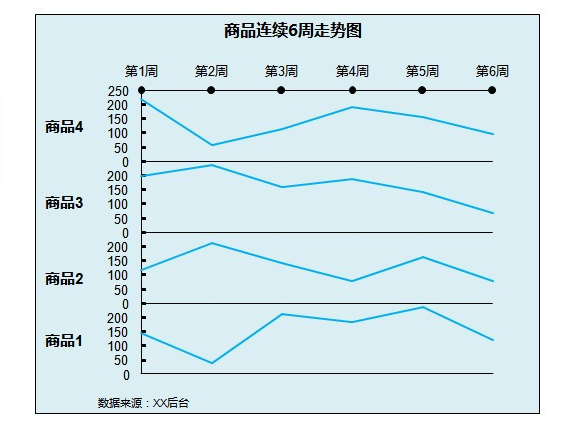

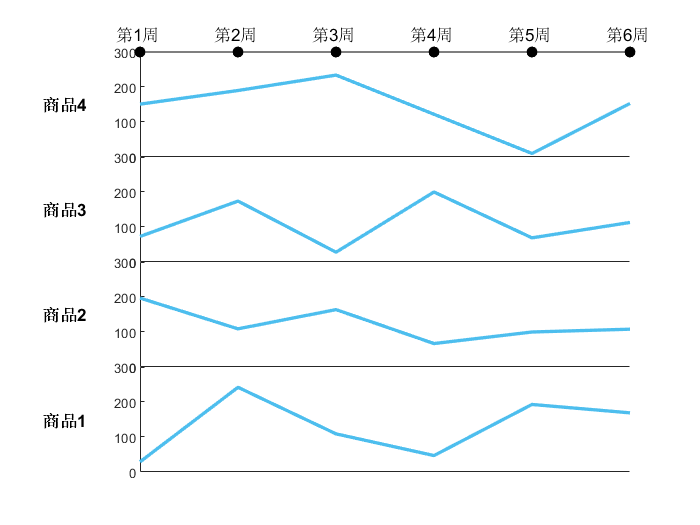

clear;clc;
x = 1:6;
y = randi(250, [4, 6]);
axes('Position', [0.2, 0.1, 0.7, 0.2]);
plot(x, y(1, :), 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
% 横着标签
text(0, 150, '商品1', 'FontWeight', 'bold');
ylim([0, 300]);
% 标签去掉
set(gca, 'XTick', []);
box off
axes('Position', [0.2, 0.3, 0.7, 0.2]);
plot(x, y(2, :), 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
text(0, 150, '商品2', 'FontWeight', 'bold');
ylim([0, 300]);
set(gca, 'XTick', []);
box off
axes('Position', [0.2, 0.5, 0.7, 0.2]);
plot(x, y(3, :), 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
text(0, 150, '商品3', 'FontWeight', 'bold');
ylim([0, 300]);
set(gca, 'XTick', []);
box off
axes('Position', [0.2, 0.7, 0.7, 0.2]);
plot(x, y(4, :), 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
text(0, 150, '商品4', 'FontWeight', 'bold');
ylim([0, 300]);
% 黑色圆点连线
hold on
plot(x, 300 * ones(1, 6), 'o-k', 'MarkerFaceColor', 'k');
hold off
set(gca, 'XTick', []);
box off
% 文本
for i = 1:6
    text(i - 0.25, 350, sprintf('第%d周', i));
end